# Preprocess and Explore Time-Stamped Data Using `timetable`

This example shows how to analyze bicycle traffic patterns from sensor data using the `timetable` data container to organize and preprocess time-stamped data. The data come from sensors on Broadway Street in Cambridge, MA. The City of Cambridge provides public access to the full data set at the [Cambridge Open Data](https://data.cambridgema.gov/dataset/Eco-Totem-Broadway-Bicycle-Count/q8v9-mcfg) site.

This example shows how to perform a variety of data cleaning, munging, and preprocessing tasks such as removing missing values and synchronizing time-stamped data with different timesteps. In addition, data exploration is highlighted including visualizations and grouped calculations using the `timetable` data container to:

- Explore daily bicycle traffic

- Compare bicycle traffic to local weather conditions

- Analyze bicycle traffic on various days of the week and times of day

## Import Bicycle Traffic Data into Timetable

Import a sample of the bicycle traffic data from a comma-separated text file. The `readtable` function returns the data in a table. Display the first eight rows using the `head` function.

bikeTbl = readtable('BicycleCounts.csv');
head(bikeTbl)

The data have timestamps, so it is convenient to use a timetable to store and analyze the data. A timetable is similar to a table, but includes timestamps that are associated with the rows of data. The timestamps, or row times, are represented by `datetime` or `duration` values. `datetime` and `duration` are the recommended data types for representing points in time or elapsed times, respectively.

Convert `bikeTbl` into a timetable using the `table2timetable` function. You must use a conversion function because `readtable` returns a table. `table2timetable` converts the first `datetime` or `duration` variable in the table into the row times of a timetable. The row times are metadata that label the rows. However, when you display a timetable, the row times and timetable variables are displayed in a similar fashion. Note that the table has five variables whereas the timetable has four.  

bikeData = table2timetable(bikeTbl);
head(bikeData)
whos bikeTbl bikeData

## Access Times and Data

Convert the `Day` variable to categorical. The categorical data type is designed for data that consists of a finite set of discrete values, such as the names of the days of the week. List the categories so they display in day order. Use dot subscripting to access variables by name. 

bikeData.Day = categorical(bikeData.Day,{'Sunday','Monday','Tuesday',...
                       'Wednesday','Thursday','Friday','Saturday'});  

In a timetable, the times are treated separately from the data variables. Access the `Properties` of the timetable to show that the row times are the first dimension of the timetable, and the variables are the second dimension. The `DimensionNames` property shows the names of the two dimensions, while the `VariableNames` property shows the names of the variables along the second dimension.

bikeData.Properties

By default, `table2timetable` assigned `Timestamp` as the first dimension name when it converted the table to a timetable, since this was the variable name from the original table. You can change the names of the dimensions, and other timetable metadata, through the `Properties`.

Change the names of the dimensions to `Time` and `Data`.

bikeData.Properties.DimensionNames = {'Time' 'Data'};
bikeData.Properties

Display the first eight rows of the timetable.

head(bikeData)

Determine the number of days that elapsed between the latest and earliest row times. The variables can be accessed by dot notation when referencing variables one at a time.

elapsedTime = max(bikeData.Time) - min(bikeData.Time)
elapsedTime.Format = 'd'

To examine the typical bicycle counts on a given day, calculate the means for the total number of bikes, and the numbers travelling westbound and eastbound.

Return the numeric data as a matrix by indexing into the contents of `bikeData` using curly braces. Display the first eight rows. Use standard table subscripting to access multiple variables.

counts = bikeData{:,2:end};
counts(1:8,:)

Since the mean is appropriate for only the numeric data, you can use the `vartype` function to select the numeric variables. `vartype` can be more convenient than manually indexing into a table or timetable to select variables. Calculate the means and omit `NaN` values.

counts = bikeData{:,vartype('numeric')};
mean(counts,'omitnan')

## Select Data by Date and Time of Day

To determine how many people bicycle during a holiday, examine the data on the 4th of July holiday. Index into the timetable by row times for July 4, 2015. When you index on row times, you must match times exactly. You can specify the time indices as `datetime` or `duration` values, or as character vectors that can be converted to dates and times. You can specify multiple times as an array.

Index into `bikeData` with specific dates and times to extract data for July 4, 2015. If you specify the date only, then the time is assumed to be midnight, or 00:00:00.

bikeData('2015-07-04',:)
d = {'2015-07-04 08:00:00','2015-07-04 09:00:00'};
bikeData(d,:)

It would be tedious to use this strategy to extract the entire day. You can also specify ranges of time without indexing on specific times. To create a time range subscript as a helper, use the `timerange` function.

Subscript into the timetable using a time range for the entire day of July 4, 2015. Specify the start time as midnight on July 4, and the end time as midnight on July 5. By default, `timerange` covers all times starting with the start time and up to, but not including, the end time. Plot the bicycle counts over the course of the day.

tr = timerange('2015-07-04','2015-07-05');
jul4 = bikeData(tr,'Total');
head(jul4)

bar(jul4.Time,jul4.Total)
ylabel('Bicycle Counts')
title('Bicycle Counts on July 4, 2015')

From the plot, there is more volume throughout the day, leveling off in the afternoon. Because many businesses are closed, the plot does not show typical traffic during commute hours. Spikes later in the evening can be attributed to celebrations with fireworks, which occur after dark. To examine these trends more closely, the data should be compared to data for typical days.

Compare the data for July 4 to data for the rest of the month of July.

jul = bikeData(timerange('2015-07-01','2015-08-01'),:);
plot(jul.Time,jul.Total)
hold on
plot(jul4.Time,jul4.Total)
ylabel('Total Count')
title('Bicycle Counts in July')
hold off
legend('Bicycle Count','July 4 Bicycle Count')

The plot shows variations that can be attributed to traffic differences between weekdays and weekends. The traffic patterns for July 4 and 5 are consistent with the pattern for weekend traffic. July 5 is a Monday but is often observed as a holiday. These trends can be examined more closely with further preprocessing and analysis.

## Preprocess Times and Data Using `timetable`

Time-stamped data sets are often messy and may contain anomalies or errors. Timetables are well suited for resolving anomalies and errors. 

A timetable does not have to have its row times in any particular order. It can contain rows that are not sorted by their row times. A timetable can also contain multiple rows with the same row time, though the rows can have different data values. Even when row times are sorted and unique, they can differ by time steps of different sizes. A timetable can even contain `NaT` or `NaN` values to indicate missing row times.

The `timetable` data type provides a number of different ways to resolve missing, duplicate, or nonuniform times. You can also resample or aggregate data to create a *regular* timetable. When a timetable is regular, it has row times that are sorted and unique, and have a uniform or evenly spaced time step between them.

- To find missing row times, use `ismissing`.

- To remove missing times and data, use `rmmissing`.

- To sort a timetable by its row times, use `sortrows`.

- To make a timetable with unique and sorted row times, use `unique` and `retime`.

- To make a regular timetable, specify a uniformly spaced time vector and use `retime`.

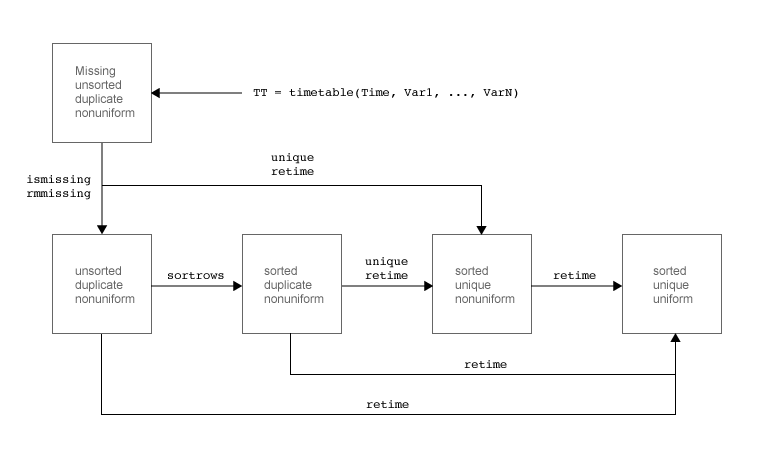

## **Sort in Time Order**

Determine if the timetable is sorted. A timetable is sorted if its row times are listed in ascending order.

issorted(bikeData)

Sort the timetable. The `sortrows` function sorts the rows by their row times, from earliest to latest time. If there are rows with duplicate row times, then `sortrows` copies all the duplicates to the output.

bikeData = sortrows(bikeData);
issorted(bikeData)

## Identify and Remove Missing Times and Data

A timetable can have missing data indicators in its variables or its row times. For example, you can indicate missing numeric values as `NaN`s, and missing datetime values as `NaT`s. You can assign, find, remove, and fill missing values with the `standardizeMissing`, `ismissing`, `rmmissing`, and `fillmissing` functions, respectively.

Find and count the missing values in the timetable variables. In this example, missing values indicate circumstances when no data were collected.

missData = ismissing(bikeData);
sum(missData)

The output from `ismissing` is a `logical` matrix, the same size as the table, identifying missing data values as true. Display any rows which have missing data indicators.

idx = any(missData,2);
bikeData(idx,:)

`ismissing(bikeData)` finds missing data in the timetable variables only, not the times. To find missing row times, call `ismissing` on the row times.

missTimes = ismissing(bikeData.Time);
bikeData(missTimes,:)

In this example, missing times or data values indicate measurement errors and can be excluded. Remove rows of the table containing missing data values and missing row times using `rmmissing`. 

bikeData = rmmissing(bikeData);
sum(ismissing(bikeData))
sum(ismissing(bikeData.Time))

## Remove Duplicate Times and Data

Determine if there are duplicate times and/or duplicate rows of data. You might want to exclude exact duplicates, as these can also be considered measurement errors. Identify duplicate times by finding where the difference between the sorted times is exactly zero.

idx = diff(bikeData.Time) == 0;
dup = bikeData.Time(idx)

Three times are repeated and November 19, 2015, is repeated twice. Examine the data associated with the repeated times.

bikeData(dup(1),:)
bikeData(dup(2),:)

The first has duplicated times but non-duplicate data, whereas the others are entirely duplicated. Timetable rows are considered duplicates when they contain identical row times and identical data values across the rows. You can use `unique` to remove duplicate rows in the timetable. The `unique` function also sorts the rows by their row times.

bikeData = unique(bikeData); 

The rows with duplicate times but non-duplicate data require some interpretation. Examine the data around those times.

d = dup(1) + hours(-2:2);
bikeData(d,:)

In this case, the duplicate time may have been mistaken since the data and surrounding times are consistent. Though it appears to represent 01:00:00, it is uncertain what time this should have been. The data can be accumulated to account for the data at both time points.

sum(bikeData{dup(1),2:end})

This is only one case which can be done manually. However, for many rows, the `retime` function can perform this calculation. Accumulate the data for the unique times using the `sum` function to aggregate. The sum is appropriate for numeric data but not the categorical data in the timetable. Use `vartype` to identify the numeric variables. 

vt = vartype('numeric');
t = unique(bikeData.Time);
numData = retime(bikeData(:,vt),t,'sum');
head(numData)

You cannot sum the categorical data, but since one label represents the whole day, take the first value on each day. You can perform the `retime` operation again with the same time vector and concatenate the timetables together. 

vc = vartype('categorical');
catData = retime(bikeData(:,vc),t,'firstvalue');
bikeData = [catData,numData];
bikeData(d,:)

## Examine Uniformity of Time Interval

The data appear to have a uniform time step of one hour. To determine if this is true for all the row times in the timetable, use the `isregular` function. `isregular` returns `true` for sorted, evenly-spaced times (monotonically increasing), with no duplicate or missing times (`NaT` or `NaN`).

isregular(bikeData)

The output of `0`, or `false`, indicates that the times in the timetable are not evenly spaced. Explore the time interval in more detail.

dt = diff(bikeData.Time);
[min(dt); max(dt)]

To put the timetable on a regular time interval, use `retime` or `synchronize` and specify the time interval of interest.

## Determine Daily Bicycle Volume

Determine the counts per day using the `retime` function. Accumulate the count data for each day using the `sum` method. This is appropriate for numeric data but not the categorical data in the timetable. Use `vartype` to identify the variables by data type. 

dayCountNum = retime(bikeData(:,vt),'daily','sum');
head(dayCountNum)

As above, you can perform the `retime` operation again to represent the categorical data using an appropriate method and concatenate the timetables together. 

dayCountCat = retime(bikeData(:,vc),'daily','firstvalue');
dayCount = [dayCountCat,dayCountNum];
head(dayCount)

## Synchronize Bicycle Count and Weather Data

Examine the effect of weather on cycling behavior by comparing the bicycle count with weather data. Load the weather timetable which includes historical weather data from Boston, MA, including storm events. 

load BostonWeatherData
head(weatherData)

To summarize the times and variables in the timetable, use the `summary` function.  

summary(weatherData)

Combine the bicycle data with the weather data to a common time vector using `synchronize`. You can resample or aggregate timetable data using any of the methods documented on the reference page for the `synchronize` function.

Synchronize the data from both timetables to a common time vector, constructed from the intersection of their individual daily time vectors.

data = synchronize(dayCount,weatherData,'intersection');
head(data)

Compare bicycle traffic counts and outdoor temperature on separate y axes to examine the trends. Remove the weekends from the data for visualization.

idx = ~isweekend(data.Time);  
weekdayData = data(idx,{'TemperatureF','Total'});
figure
yyaxis left
plot(weekdayData.Time, weekdayData.Total) 
ylabel('Bicycle Count')
yyaxis right
plot(weekdayData.Time,weekdayData.TemperatureF) 
ylabel('Temperature (\circ F)')
title('Bicycle Counts and Temperature Over Time')
xlim([min(data.Time) max(data.Time)])

The plot shows that the traffic and weather data might follow similar trends. Zoom in on the plot.

xlim([datetime('2015-11-01'),datetime('2016-05-01')])

The trends are similar, indicating that fewer people cycle on colder days. 

## Analyze by Day of Week and Time of Day

Examine the data based on different intervals such as day of the week and time of day. Determine the total counts per day using `varfun` to perform grouped calculations on variables. Specify the `sum` function with a function handle and the grouping variable and preferred output type using name-value pairs. 

byDay = varfun(@sum,bikeData,'GroupingVariables','Day',...
             'OutputFormat','table')

figure
bar(byDay{:,{'sum_Westbound','sum_Eastbound'}})
legend({'Westbound','Eastbound'},'Location','eastoutside')
xticklabels({'Sun','Mon','Tue','Wed','Thu','Fri','Sat'})
title('Bicycle Count by Day of Week')

The bar plot indicates that traffic is heavier on weekdays. Also, there is a difference in the Eastbound and Westbound directions. This might indicate that people tend to take different routes when entering and leaving the city. Another possibility is that some people enter on one day and return on another day.

Determine the hour of day and use `varfun` for calculations by group.

bikeData.HrOfDay = hour(bikeData.Time);
byHr = varfun(@mean,bikeData(:,{'Westbound','Eastbound','HrOfDay'}),...
    'GroupingVariables','HrOfDay','OutputFormat','table');
head(byHr)

bar(byHr{:,{'mean_Westbound','mean_Eastbound'}})
legend('Westbound','Eastbound','Location','eastoutside')
xlabel('Hour of Day')
ylabel('Bicycle Count')
title('Mean Bicycle Count by Hour of Day')

There are traffic spikes at the typical commute hours, around 9:00 a.m. and 5:00 p.m. Also, the trends between the Eastbound and Westbound directions are different. In general, the Westbound direction is toward residential areas surrounding the Cambridge area and toward the universities. The Eastbound direction is toward Boston.

The traffic is heavier later in the day in the Westbound direction compared to the Eastbound direction. This might indicate university schedules and traffic due to restaurants in the area. Examine the trend by day of week as well as hour of day.

byHrDay = varfun(@sum,bikeData,'GroupingVariables',{'HrOfDay','Day'},...
    'OutputFormat','table');
head(byHrDay)

To arrange the timetable so that the days of the week are the variables, use the `unstack` function. 

hrAndDayWeek = unstack(byHrDay(:,{'HrOfDay','Day','sum_Total'}),'sum_Total','Day'); 
head(hrAndDayWeek)

ribbon(hrAndDayWeek.HrOfDay,hrAndDayWeek{:,2:end})
ylim([0 24])
xlim([0 8])
xticks(1:7)
xticklabels({'Sun','Mon','Tue','Wed','Thu','Fri','Sat'})
ylabel('Hour')
title('Bicycle Count by Hour and Day of Week')

There are similar trends for the regular work days of Monday through Friday, with peaks at rush hour and traffic tapering off in the evening. Friday has less volume, though the overall trend is similar to the other work days. The trends for Saturday and Sunday are similar to each other, without rush hour peaks and with more volume later in the day. The late evening trends are also similar for Monday through Friday, with less volume on Friday.

## Analyze Traffic During Rush Hour

To examine the overall time of day trends, split up the data by rush hour times. It is possible to use different times of day or units of time using the `discretize` function. For example, separate the data into groups for `AM`, `AMRush`, `Day`, `PMRush`, `PM`. Then use `varfun` to calculate the mean by group.

bikeData.HrLabel = discretize(bikeData.HrOfDay,[0,6,10,15,19,24],'categorical',...
    {'AM','RushAM','Day','RushPM','PM'});
byHrBin = varfun(@mean,bikeData(:,{'Total','HrLabel'}),'GroupingVariables','HrLabel',...
    'OutputFormat','table')

bar(byHrBin.mean_Total)
cats = categories(byHrBin.HrLabel);
xticklabels(cats)
title('Mean Bicycle Count During Rush Hours')

In general, there is about twice as much traffic in this area during the evening and morning rush hours compared to other times of the day. There is very little traffic in this area in the early morning, but there is still significant traffic in the evening and late evening, comparable to the day outside of the morning and evening rush hours.

*Copyright 2018 The MathWorks, Inc.*